folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\"

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\"

fileName = ["Test 1", "Test 2","Test 3","Test 4"]

fileName = 1×4 string array
    "Test 1"    "Test 2"    "Test 3"    "Test 4"


imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Speed Step Graphs\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Speed Step Graphs\"

figureWidth = 700; % Width in pixels
figureHeight = 500; % Height in pixels

% Set the figure size
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

for file = 1:length(fileName)
    filePath = fullfile(folderPath,fileName(file) + ".csv") 
    resultsFrequencySweep = readtable(filePath,"VariableNamingRule","preserve")
    previousSpeed = 40;
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\Test 1.csv"

resultsFrequencySweep = 12398×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-16 20:40:09         40             1.73              20               22                 18               -28            -5             -7             -2     
    2024-10-16 20:40:09         40             1.73              20               22                 18    

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\Test 2.csv"

resultsFrequencySweep = 9303×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-16 20:43:21         40             4.46              20               25                 43               -59             28            -46             40    
    2024-10-16 20:43:21         40             4.46              20               25                 43     

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\Test 3.csv"

resultsFrequencySweep = 8597×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-16 20:46:08         40             41.67             20               15                 24               -67            -31            -37            -49    
    2024-10-16 20:46:08         40             41.67             20               15                 24     

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\Test 4.csv"

resultsFrequencySweep = 7514×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-16 20:48:22         60             1.77              20               27                 43               -33             -3            -14              1    
    2024-10-16 20:48:22         60             1.77              20               27                 43     

    aveargaePitch = zeros(1,length(resultsFrequencySweep.("Current Pitch 1")));
    for i = 1:length(resultsFrequencySweep.("Current Pitch 1"))
        aveargaePitch(i) = (resultsFrequencySweep.("Current Pitch 1")(i) + resultsFrequencySweep.("Current Pitch 2")(i))/2;
    end

    
    resultsFrequencySweep.("Load Cell 1") = -(resultsFrequencySweep.("Load Cell 1") - resultsFrequencySweep.("Load Cell 1")(1)).*0.0098;
    loadcell1 = rmmissing(resultsFrequencySweep.("Load Cell 1"));
    loadcell1(isoutlier(resultsFrequencySweep.("Load Cell 1"), 'mean')) = NaN;
    loadcell1 = fillmissing(loadcell1, 'linear');
    
    resultsFrequencySweep.("Load Cell 2")  = -(resultsFrequencySweep.("Load Cell 2")  - resultsFrequencySweep.("Load Cell 2") (1)).*0.0098;
    loadcell2 = rmmissing(resultsFrequencySweep.("Load Cell 2") );
    % loadcell2(isoutlier(resultsFrequencySweep.("Load Cell 2") , 'mean')) = NaN;
    loadcell2 = fillmissing(loadcell2, 'linear');
    
    resultsFrequencySweep.("Load Cell 3")  = -((resultsFrequencySweep.("Load Cell 3") ) - (resultsFrequencySweep.("Load Cell 3") (1))).*0.0098.*0.9;
    loadcell3 = rmmissing(resultsFrequencySweep.("Load Cell 3") );
    % loadcell3(isoutlier(resultsFrequencySweep.("Load Cell 3") , 'mean')) = NaN;
    loadcell3 = fillmissing(loadcell3, 'linear');
    
    resultsFrequencySweep.("Load Cell 4")  = -((resultsFrequencySweep.("Load Cell 4") ) - (resultsFrequencySweep.("Load Cell 4") (1))).*0.0098.*0.8;
    loadcell4 = rmmissing(resultsFrequencySweep.("Load Cell 4") );
    % loadcell4(isoutlier(resultsFrequencySweep.("Load Cell 4") , 'mean')) = NaN;
    loadcell4 = fillmissing(loadcell4, 'linear');
    
    aveargaeLoadcells = zeros(1,length(loadcell1));
    for i = 1:length(loadcell1)
        aveargaeLoadcells(i) = (loadcell1(i) + loadcell1(i) + loadcell1(i) + loadcell1(i));
    end
    figure;
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell1)),loadcell1,'DisplayName','Load Cell 1')
    hold on
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell2)),loadcell2,'DisplayName','Load Cell 2')
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell3)),loadcell3,'DisplayName','Load Cell 3')
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell4)),loadcell4,'DisplayName','Load Cell 4')
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(aveargaeLoadcells)),aveargaeLoadcells,"--r",'DisplayName','Combined Load Cells')
    xlim([0,length(resultsFrequencySweep.Timestamp)*10e-3])
    % xline(30)
    hold off
    ylabel('Lift [N]');
    xlabel('Time [s]');
    title(sprintf('Unfiltered Load Cell Readings for a %d° pitch', resultsFrequencySweep.("Target Pitch")(1)));
    legend;
    TotalLoadcellScalled = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcells)), aveargaeLoadcells, 1:length(aveargaePitch), 'linear')

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


TotalLoadcellScalled =          0    0.0008    0.0016    0.0024    0.0033    0.0041    0.0049    0.0057    0.0065    0.0073    0.0081    0.0089    0.0098    0.0106    0.0114    0.0122    0.0130    0.0138    0.0146    0.0155    0.0163    0.0171    0.0179    0.0187    0.0195    0.0203    0.0211    0.0220    0.0228    0.0236    0.0244    0.0252    0.0260    0.0268    0.0277    0.0285    0.0293    0.0301    0.0309    0.0317    0.0325    0.0333    0.0342    0.0350    0.0358    0.0366    0.0374    0.0382    0.0390    0.0385


TotalLoadcellScalled =          0   -0.0041   -0.0081   -0.0122   -0.0162   -0.0203   -0.0244   -0.0284   -0.0325   -0.0365   -0.0406   -0.0446   -0.0487   -0.0528   -0.0568   -0.0609   -0.0649   -0.0690   -0.0731   -0.0771   -0.0812   -0.0852   -0.0893   -0.0933   -0.0974   -0.1015   -0.1055   -0.1096   -0.1136   -0.1177   -0.1218   -0.1258   -0.1299   -0.1339   -0.1380   -0.1421   -0.1461   -0.1502   -0.1542   -0.1583   -0.1623   -0.1664   -0.1705   -0.1745   -0.1786   -0.1826   -0.1867   -0.1908   -0.1948   -0.1822


TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


    linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell2))

ans =          0    0.4732    0.9464    1.4196    1.8928    2.3660    2.8392    3.3124    3.7856    4.2589    4.7321    5.2053    5.6785    6.1517    6.6249    7.0981    7.5713    8.0445    8.5177    8.9909    9.4641    9.9373   10.4105   10.8837   11.3569   11.8302   12.3034   12.7766   13.2498   13.7230   14.1962   14.6694   15.1426   15.6158   16.0890   16.5622   17.0354   17.5086   17.9818   18.4550   18.9282   19.4015   19.8747   20.3479   20.8211   21.2943   21.7675   22.2407   22.7139   23.1871


ans =          0    0.4820    0.9640    1.4461    1.9281    2.4101    2.8921    3.3741    3.8562    4.3382    4.8202    5.3022    5.7842    6.2663    6.7483    7.2303    7.7123    8.1944    8.6764    9.1584    9.6404   10.1224   10.6045   11.0865   11.5685   12.0505   12.5325   13.0146   13.4966   13.9786   14.4606   14.9426   15.4247   15.9067   16.3887   16.8707   17.3527   17.8348   18.3168   18.7988   19.2808   19.7628   20.2449   20.7269   21.2089   21.6909   22.1730   22.6550   23.1370   23.6190


ans =          0    0.4830    0.9660    1.4489    1.9319    2.4149    2.8979    3.3808    3.8638    4.3468    4.8298    5.3128    5.7957    6.2787    6.7617    7.2447    7.7276    8.2106    8.6936    9.1766    9.6596   10.1425   10.6255   11.1085   11.5915   12.0744   12.5574   13.0404   13.5234   14.0063   14.4893   14.9723   15.4553   15.9383   16.4212   16.9042   17.3872   17.8702   18.3531   18.8361   19.3191   19.8021   20.2851   20.7680   21.2510   21.7340   22.2170   22.6999   23.1829   23.6659


ans =          0    0.4817    0.9633    1.4450    1.9267    2.4083    2.8900    3.3717    3.8533    4.3350    4.8167    5.2983    5.7800    6.2617    6.7433    7.2250    7.7067    8.1883    8.6700    9.1517    9.6333   10.1150   10.5967   11.0783   11.5600   12.0417   12.5233   13.0050   13.4867   13.9683   14.4500   14.9317   15.4133   15.8950   16.3767   16.8583   17.3400   17.8217   18.3033   18.7850   19.2667   19.7483   20.2300   20.7117   21.1933   21.6750   22.1567   22.6383   23.1200   23.6017


    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    imageFilePath = fullfile(imageFolderPath,"Unfiltered Loadcell Readings-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell1)),loadcell1)
    period = 0.44;
    fs = 1/period;   % Sampling Frequency
    nyquist_freq = fs/2 ;
    previousItterationPoint = 1

previousItterationPoint = 1

previousItterationPoint = 1

previousItterationPoint = 1

previousItterationPoint = 1

    % for changeInSpeeds = 1:length(resultsFrequencySweep.("Target Speed"))
    %     if resultsFrequencySweep.("Target Speed")(changeInSpeeds) > previousSpeed
    %         resultsFrequencySweep.("Target Speed")(changeInSpeeds)
    %         changeInSpeeds
    %         position = floor(changeInSpeeds/length(resultsFrequencySweep.("Target Speed")).*length(aveargaeLoadcells))
    %         previousSpeed = resultsFrequencySweep.("Target Speed")(changeInSpeeds)
    %         speed = (resultsFrequencySweep.("Target Speed")(changeInSpeeds-1));
    %         rotor_freq = speed * 2*pi/60/(2*pi);
    %         aliasing_freq = rotor_freq/nyquist_freq;
    %         if aliasing_freq < 2 && aliasing_freq > 1 || aliasing_freq > 3
    %             aliasing_freq = 2 - aliasing_freq;
    %         end
    %         plot_aliais = mod(aliasing_freq,aliasing_freq - mod(aliasing_freq/1,1));
    % 
    %         L = position - previousItterationPoint-1;         % Length of the signal
    %         Y = fft(aveargaeLoadcells(previousItterationPoint:position-1) - mean(aveargaeLoadcells(previousItterationPoint:position-1)));            % Perform FFT
    %         aveargaeLoadcells(previousItterationPoint:position-1)
    % 
    %         P2 = abs(Y/L);                     % Two-sided spectrum
    %         P1 = P2(1:floor(L/2)+1);           % Single-sided spectrum
    %         P1(2:end-1) = 2*P1(2:end-1);       % Account for energy in both sides of spectrum
    %         f = fs/L*(0:(L/2));                % Frequency axis
    % 
    %         % abs(P2);
    % 
    %         % Single-Sided Spectrum
    %         plot(f, P1,"LineWidth",3);
    % 
    %         % xlim([0,f(end)])
    %         title(sprintf('Single-Sided FFT of Combined Loadcell Output for %d rpm with a %d° pitch', resultsFrequencySweep.("Target Speed")(changeInSpeeds-1), resultsFrequencySweep.("Target Pitch")(changeInSpeeds-1)));
    %         xlabel('Frequency (Hz)');
    %         ylabel('Amplitude of Combined Loadcells');
    %         xline(plot_aliais,'--r','linewidth',2);
    %         previousItterationPoint = position;
    %         pause(2)
    %     end
    % end
    % Demean the signal to remove the DC component
    %
    
    % for speedChange = 130:5:150
    
    speed = (resultsFrequencySweep.("Current Speed")(floor(length(resultsFrequencySweep.("Current Speed"))/2)));
    rotor_freq = 135 * 2*pi/60/(2*pi);
    period = 0.44;
    fs = 1/period;   % Sampling Frequency
    nyquist_freq = fs/2 ;
    aliasing_freq = rotor_freq/nyquist_freq

aliasing_freq = 1.9800

aliasing_freq = 1.9800

aliasing_freq = 1.9800

aliasing_freq = 1.9800

    if aliasing_freq < 2 && aliasing_freq > 1 && aliasing_freq < 3
        aliasing_freq = 2 - aliasing_freq;
    else if aliasing_freq > 3
                aliasing_freq = 1-(aliasing_freq-3);
    end
    
    end
    aliasing_freq

aliasing_freq = 0.0200

aliasing_freq = 0.0200

aliasing_freq = 0.0200

aliasing_freq = 0.0200

     mod(aliasing_freq,aliasing_freq)

ans = 0

ans = 0

ans = 0

ans = 0

    plot_aliais = mod(aliasing_freq,aliasing_freq - mod(aliasing_freq/1,1))

plot_aliais = 0.0200

plot_aliais = 0.0200

plot_aliais = 0.0200

plot_aliais = 0.0200

    
    L = length(aveargaeLoadcells);         % Length of the signal
    Y = fft(aveargaeLoadcells);            % Perform FFT
    
    
    P2 = abs(Y/L);                     % Two-sided spectrum
    P1 = P2(1:floor(L/2)+1);           % Single-sided spectrum
    P1(2:end-1) = 2*P1(2:end-1);       % Account for energy in both sides of spectrum
    f = fs/L*(0:(L/2));                % Frequency axis
    
    % abs(P2);
    
    % Single-Sided Spectrum
    figure;
    plot(f, P1,"LineWidth",3,"DisplayName", "FFT");
    xlim([0,f(end)])
    title(sprintf('Single-Sided FFT of Combined Load cell Output for %d rpm',135));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude of Combined Loadcells');
    xline(plot_aliais,'--r','linewidth',2,"DisplayName",sprintf('Aliasing Frequency for %d rpm', resultsFrequencySweep.("Target Speed")(1)));
    legend;

    % end
    set(gcf, 'Position', [100, 100, 600, 500]);
    imageFilePath = fullfile(imageFolderPath,"FFT-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
    
    cutOffFrequency = 0.2;
    nOrder = 4;
    
    [b,a] = butter(nOrder,cutOffFrequency/(fs/2));
    loadcell1Filtered = filtfilt(b,a,loadcell1);
    loadcell2Filtered = filtfilt(b,a,loadcell2);
    loadcell3Filtered = filtfilt(b,a,loadcell3);
    loadcell4Filtered = filtfilt(b,a,loadcell4);
    
    aveargaeLoadcellsFiltered = zeros(1,length(loadcell1Filtered));
    
    
    for i = 1:length(loadcell1Filtered)
        aveargaeLoadcellsFiltered(i) = (loadcell1Filtered(i) + loadcell2Filtered(i) + loadcell3Filtered(i) + loadcell4Filtered(i));
    end
    figure;
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell1Filtered)),loadcell1Filtered,'DisplayName','Load Cell 1')
    hold on
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell2Filtered)),loadcell2Filtered,'DisplayName','Load Cell 2')
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell3Filtered)),loadcell3Filtered,'DisplayName','Load Cell 3')
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(loadcell4Filtered)),loadcell4Filtered,'DisplayName','Load Cell 4')
    plot(linspace(0,length(resultsFrequencySweep.Timestamp)*10e-3, length(aveargaeLoadcellsFiltered)),aveargaeLoadcellsFiltered,'--r', 'DisplayName','Combined Load Cells')
    % yline(mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))),'-.b','DisplayName','Average Lift')
    hold off
    xlim([0,length(resultsFrequencySweep.Timestamp)*10e-3])
    ylabel('Lift [N]');
    xlabel('Time [s]');
    title(sprintf('Filtered Load Cell Readings for a %d° pitch', resultsFrequencySweep.("Target Pitch")(1)));
    legend;
    
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Lift Generated-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
    
    predictedThrustFunction = @(x) 0.01805 .* (x .* pi/30).^2 + 0.002216 .* (x .* pi/30).^2/0.2625 .*sind(20);
    predictedThrust = predictedThrustFunction(sgolayfilt(resultsFrequencySweep.("Current Speed"), 4, 111));

    mydata = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')

mydata =     0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0004


mydata =     0.0020    0.0010    0.0001   -0.0009   -0.0019   -0.0028   -0.0038   -0.0047   -0.0057   -0.0066   -0.0076   -0.0086   -0.0095   -0.0105   -0.0114   -0.0124   -0.0133   -0.0143   -0.0153   -0.0162   -0.0172   -0.0181   -0.0191   -0.0200   -0.0210   -0.0220   -0.0229   -0.0239   -0.0248   -0.0258   -0.0267   -0.0277   -0.0287   -0.0296   -0.0306   -0.0315   -0.0325   -0.0334   -0.0344   -0.0354   -0.0363   -0.0373   -0.0382   -0.0392   -0.0401   -0.0411   -0.0421   -0.0430   -0.0440   -0.0446


mydata =     0.0018    0.0024    0.0030    0.0037    0.0043    0.0049    0.0055    0.0061    0.0067    0.0073    0.0080    0.0086    0.0092    0.0098    0.0104    0.0110    0.0116    0.0123    0.0129    0.0135    0.0141    0.0147    0.0153    0.0160    0.0166    0.0172    0.0178    0.0184    0.0190    0.0196    0.0203    0.0209    0.0215    0.0221    0.0227    0.0233    0.0240    0.0246    0.0252    0.0258    0.0264    0.0270    0.0276    0.0283    0.0289    0.0295    0.0301    0.0307    0.0313    0.0319


mydata =    -0.0051   -0.0062   -0.0073   -0.0083   -0.0094   -0.0105   -0.0116   -0.0126   -0.0137   -0.0148   -0.0159   -0.0169   -0.0180   -0.0191   -0.0202   -0.0212   -0.0223   -0.0234   -0.0245   -0.0255   -0.0266   -0.0277   -0.0288   -0.0298   -0.0309   -0.0320   -0.0331   -0.0341   -0.0352   -0.0363   -0.0374   -0.0385   -0.0395   -0.0406   -0.0417   -0.0428   -0.0438   -0.0449   -0.0460   -0.0471   -0.0481   -0.0492   -0.0503   -0.0514   -0.0524   -0.0535   -0.0546   -0.0557   -0.0567   -0.0574


    fileName(file)

ans = "Test 1"

ans = "Test 2"

ans = "Test 3"

ans = "Test 4"

    RMSE = sqrt(mean(mydata-predictedThrust').^2)

RMSE = 0.6692

RMSE = 0.2430

RMSE = 1.7590

RMSE = 1.0465

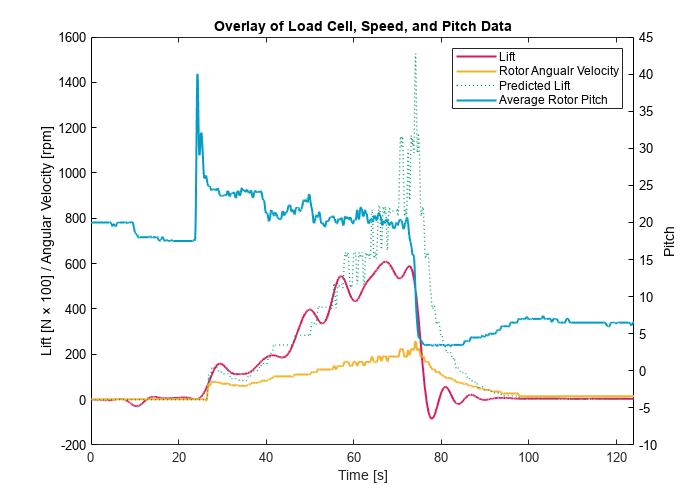

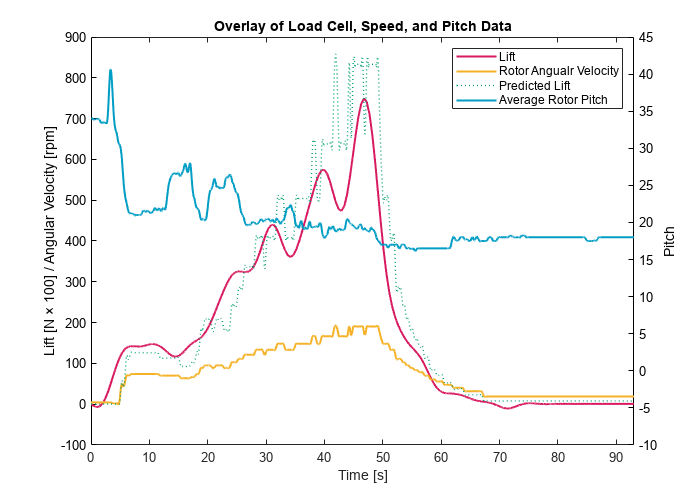

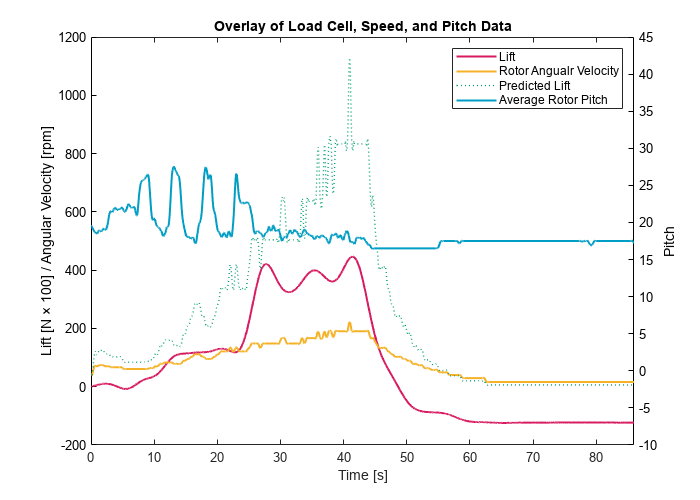

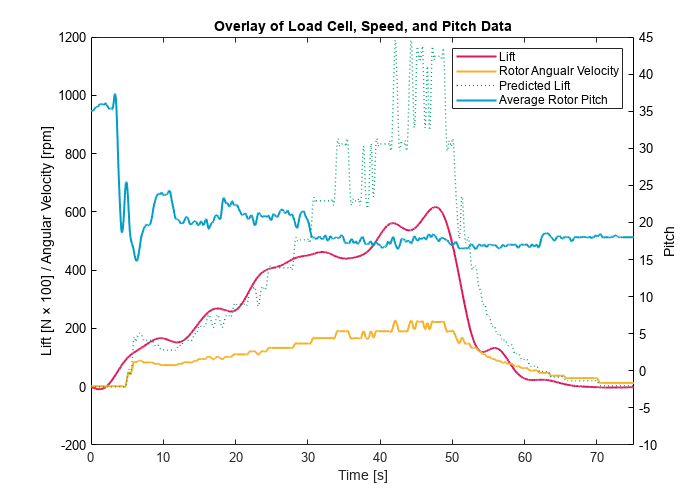


    clear alpha
    yyaxis left
    plot((1:length(aveargaePitch)).*10e-3, interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')*100,'color',"#D81B60", 'DisplayName', 'Lift', 'LineWidth', 1.5);
    hold on;
    plot((1:length(aveargaePitch)).*10e-3, sgolayfilt(resultsFrequencySweep.("Current Speed"), 4, 111),'Linestyle','-', 'color',"#f5b227",'DisplayName', 'Rotor Angualr Velocity', 'LineWidth', 1.5);
    plot((1:length(aveargaePitch)).*10e-3,predictedThrust*100,'Linestyle',':','color',"#009E73", 'DisplayName', 'Predicted Lift', 'LineWidth', 1)
    alpha(0); % Set transparency for better visibility
    ylabel('Lift [N × 100] / Angular Velocity [rpm]');
    ax = gca;
    ax.YColor = 'k'; % Set color to black for consistency
    
    yyaxis right
    plot((1:length(aveargaePitch))*10e-3, sgolayfilt(aveargaePitch, 4, 111),'color',"#009DC4", 'DisplayName', 'Average Rotor Pitch', 'LineWidth', 1.5);
    alpha(0.2); % Set transparency
    ylabel('Pitch');
    ax.YColor = 'k'; % Set color to black for consistency
    ylim([-10,45])
        
    xlabel('Time [s]');
    title('Overlay of Load Cell, Speed, and Pitch Data');
    legend;
    xlim([0,length(resultsFrequencySweep.Timestamp)*10e-3])
    % grid on;
    hold off;

    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Lift, Pitch and Speed-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);

    close(gcf);

end